[x1, y1, z1, vel1, Gx1, Gy1, Gz1] = section1(0,50,125);

x1 =     0.0000    0.7933    1.5864    2.3791    3.1712    3.9625    4.7528    5.5419    6.3296    7.1157    7.9001    8.6824    9.4626   10.2403   11.0155   11.7879   12.5574   13.3237   14.0866   14.8460   15.6017   16.3534   17.1010   17.8443   18.5831   19.3173   20.0465   20.7708   21.4897   22.2033   22.9113   23.6136   24.3098   25.0000   25.6839   26.3613   27.0320   27.6960   28.3530   29.0028   29.6454   30.2805   30.9079   31.5276   32.1394   32.7430   33.3385   33.9255   34.5040   35.0737


y1 =     50    50    50    50    50    50    50    50    50    50    50    50    50    50    50    50    50    50    50    50    50    50    50    50    50    50    50    50    50    50    50    50    50    50    50    50    50    50    50    50    50    50    50    50    50    50    50    50    50    50


z1 =   125.0000  124.9937  124.9748  124.9434  124.8993  124.8427  124.7736  124.6919  124.5977  124.4911  124.3719  124.2404  124.0964  123.9401  123.7715  123.5906  123.3974  123.1921  122.9746  122.7451  122.5036  122.2500  121.9846  121.7074  121.4184  121.1177  120.8054  120.4816  120.1463  119.7997  119.4418  119.0727  118.6925  118.3013  117.8992  117.4863  117.0627  116.6285  116.1838  115.7288  115.2635  114.7881  114.3027  113.8073  113.3022  112.7875  112.2632  111.7296  111.1867  110.6347


vel1 =          0    0.3514    0.7028    1.0541    1.4054    1.7565    2.1076    2.4585    2.8093    3.1599    3.5103    3.8605    4.2105    4.5601    4.9095    5.2586    5.6073    5.9557    6.3038    6.6514    6.9986    7.3454    7.6917    8.0375    8.3828    8.7276    9.0718    9.4155    9.7585   10.1010   10.4428   10.7840   11.1245   11.4643   11.8033   12.1416   12.4792   12.8160   13.1519   13.4871   13.8214   14.1548   14.4873   14.8189   15.1496   15.4793   15.8081   16.1358   16.4626   16.7883


Gx1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Gy1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Gz1 =     1.0000    0.9996    0.9985    0.9966    0.9940    0.9906    0.9864    0.9815    0.9759    0.9695    0.9623    0.9544    0.9458    0.9364    0.9263    0.9154    0.9038    0.8915    0.8785    0.8647    0.8502    0.8350    0.8191    0.8024    0.7851    0.7671    0.7483    0.7289    0.7088    0.6880    0.6665    0.6444    0.6215    0.5981    0.5740    0.5492    0.5238    0.4977    0.4710    0.4437    0.4158    0.3873    0.3582    0.3284    0.2981    0.2672    0.2358    0.2038    0.1712    0.1381


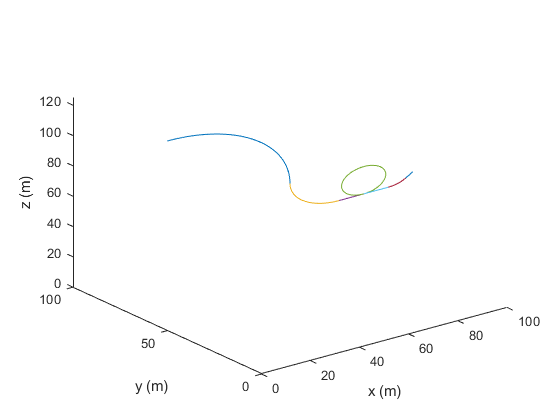

plot3(x1,y1,z1)
hold on
[x2, y2, z2, vel2, Gx2, Gy2, Gz2] = section2(x1(end),y1(end),z1(end));
plot3(x2,y2,z2)
xlabel("x (m)")
ylabel("y (m)")
zlabel("z (m)")
xlim([0 100])
ylim([0 100])
zlim([0 125])
hold on
plot3(x2,y2,z2)
[x3, y3, z3, vel3, Gx3, Gy3, Gz3] = section3(x2(end),y2(end),z2(end),10);
plot3(x3,y3,z3)
hold on
[x4,y4,z4,vel4,Gx4,Gy4,Gz4] = loopPath(x3(end),y3(end),z3(end),9,1);
plot3(x4,y4,z4)
[x5, y5, z5, vel5, Gx5, Gy5, Gz5] = section3(x4(end),y4(end),z4(end),10);
plot3(x5,y5,z5)
[x6, y6, z6, vel6, Gx6, Gy6, Gz6] = launch(x5(end),y5(end),z5(end));
plot3(x6,y6,z6)
parabolicPos = [x6(end),y6(end),z6(end)];
parabolicVel = [vel6(end)*sqrt(2)/2,0,vel6(end)*sqrt(2)/2];
[x7, y7, z7, vel7, Gx7, Gy7, Gz7, vf] = Parabola(parabolicVel,parabolicPos);
plot3(x7,y7,z7)
[x8, y8, z8, vel8, Gx8, Gy8, Gz8] = landing(x7(end),y7(end),z7(end));
plot3(x8,y8,z8)
hold off

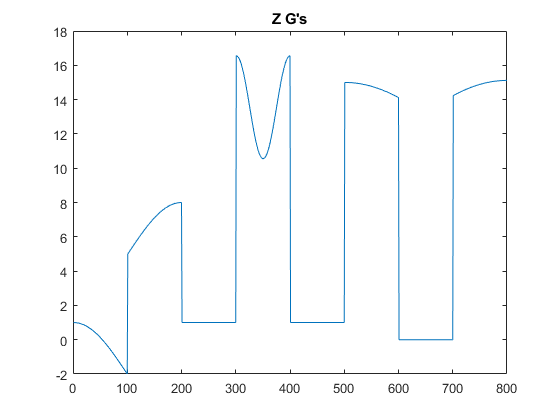

plot([Gz1 Gz2 Gz3 Gz4 Gz5 Gz6 Gz7 Gz8])
title("Z G's")
hold off

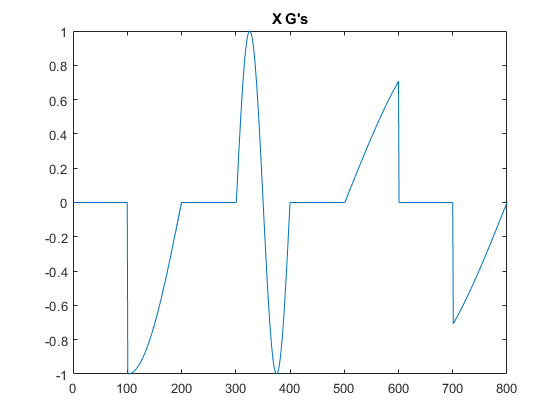

plot([Gx1 Gx2 Gx3 Gx4 Gx5 Gx6 Gx7 Gx8])
title("X G's")
hold off

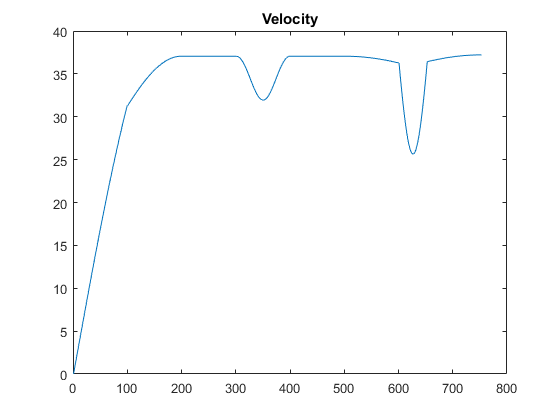

plot([vel1 vel2 vel3 vel4 vel5 vel6 vel7 vel8])
title("Velocity")
hold off

function [x, y, z, vel, Gx, Gy, Gz] = section1(xI,yI,zI)
    theta = linspace(pi/2,0,100);
    radius = 50;
    g = 9.81;
    x = radius.*cos(theta) + xI;
    y = theta.*0 + yI;
    z = radius.*sin(theta) + zI - radius;
    vel = sqrt(2 .* g .* (zI - z));
    Gz = -((vel.^2)./(g * radius)) + sin(theta);
    Gx = theta .* 0;
    Gy = theta .* 0;
%     t = linspace(0,10,100);
%     g = 9.81;
%     x = t.*0 + xI;
%     y = t.*0 + yI;
%     z = -t + zI;
%     vel = sqrt(2 .* g .* (125 - z));
%     Gz = t .* 0;
%     Gx = t .* 0;
%     Gy = t .* 0;
end
function [x, y, z, vel, Gx, Gy, Gz] = section2(xI,yI,zI)
    % circular section, G's occur perpendicular to cart, vert -> flat
    theta = linspace(pi,3*pi/2,100);
    radius = 20;
    g = 9.81;
    x = radius.*cos(theta) + radius + xI;
    y = theta.*0 + yI;
    z = radius.*sin(theta) + zI;
    vel = sqrt(2 .* g .* (125 - z));
    Gz = ((vel.^2)./(g * radius)) - sin(theta);
    Gx = cos(theta);
    Gy = theta .* 0;
end
function [x, y, z, vel, Gx, Gy, Gz] = section3(xI,yI,zI,L)
    % linear section, 1G downwards, propogates in the x direction 
    t = linspace(0,L,100);
    g = 9.81;
    x = t + xI;
    y = t.*0 + yI;
    z = t.*0 + zI;
    vel = sqrt(2 .* g .* (125 - z));
    Gz = t .* 0 + 1;
    Gx = t .* 0;
    Gy = t .* 0;
end
function [x,y,z,V,Gx,Gy,Gz] = loopPath(xI,yI,zI,r,prop)
    %% Setup
    % Note, this currently only calculated velocity correctly
    % if the path is one full loop. I need to add the calculations
    % for the velocity vector for a partial loop.
    h0 = 125; % [m] initial height
    m = 100;  % [kg] particle mass
    g = 9.81; % [m/s^2] gravity
    t = linspace(-pi/2,(prop.*2.*pi)-pi./2,100);
    %% calculating positions
    x = xI + r.*cos(t);
    z = zI + r + r.*sin(t);
    y = yI + 0.*t;         % If you change t to be multiplied by a nonzero number it becomes a helix
    %% velocity and G force calculations
    V = t.*0 + sqrt(2*g*(h0-z));
    N = m*((-sin(t)*g)+((V.^2)/r));
    Gz = t.*0 + N/(m*g);
    Gx = cos(t);
    Gy = t.*0;
    %% output
end
function [x, y, z, vel, Gx, Gy, Gz] = launch(xI,yI,zI)
    % circular section, creates platform for parabolic section
    theta = linspace(3*pi/2,7*pi/4,100);
    radius = 10;
    g = 9.81;
    x = radius.*cos(theta) + xI;
    y = theta.*0 + yI;
    z = radius.*sin(theta) + zI + radius;
    vel = sqrt(2 .* g .* (125 - z));
    Gz = ((vel.^2)./(g * radius)) - sin(theta);
    Gx = cos(theta);
    Gy = theta .* 0;
end
function [x, y, z, vel, Gx, Gy, Gz, vf] = Parabola(v0,pos0)
    %% Setup of variables and vectors
    t = linspace(0,10,100);
    g = 9.81;
    x = ones(1,length(t)).*4200; % filling with large values
    y = ones(1,length(t)).*4200; % to be trimmed later
    z = ones(1,length(t)).*4200;
    x(1) = pos0(1);
    y(1) = pos0(2);
    z(1) = pos0(3);
    i = 2;
    %% Calculating path with kinematics
    while i <= length(t)
        x(i) = (v0(1)*t(i))+x(1);
        y(i) = (v0(2)*t(i))+y(1);
        z(i) = ((v0(3)*t(i))-(0.5*g*t(i)*t(i)))+z(1);
        if z(i) <= z(1)
            i = length(t);
        end
        i = i + 1;
    end
    %% Trimming position vectors
    x = x(x ~= 4200);   % output, [meters]
    y = y(y ~= 4200);   % output, [meters]
    z = z(z ~= 4200);   % output, [meters]
    vel = sqrt(2*g.*(125-z));
    Gz = t .* 0;
    Gx = t .* 0;
    Gy = t .* 0;
    % z(end) = z(1);
    vf = [v0(1) v0(2) -v0(3)];  % output, [m/s]
end
function [x, y, z, vel, Gx, Gy, Gz] = landing(xI,yI,zI)
    % circular section, platform for parabolic landing
    theta = linspace(5*pi/4,3*pi/2,100);
    radius = 10;
    g = 9.81;
    x = radius.*cos(theta) + xI + 7.0711;
    y = theta.*0 + yI;
    z = radius.*sin(theta) + zI + 7.0711;
    vel = sqrt(2 .* g .* (125 - z));
    Gz = ((vel.^2)./(g * radius)) - sin(theta);
    Gx = cos(theta);
    Gy = theta .* 0;
end